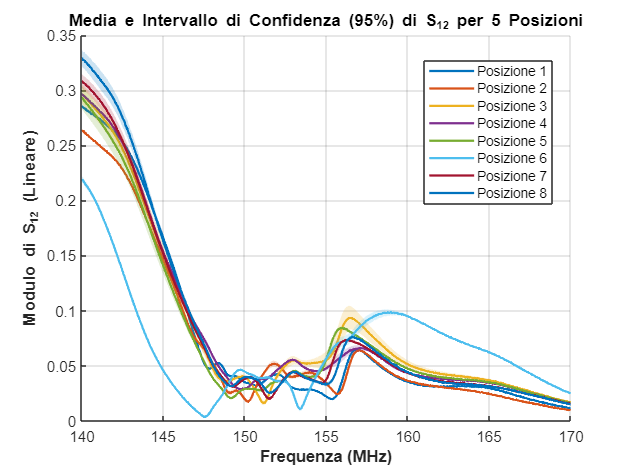

% Parametri iniziali
num_pos = 8;       % Numero di posizioni (x)
num_acq = 25;      % Numero di acquisizioni per posizione (y)

% Valore critico della distribuzione t di Student per un Intervallo di 
% Confidenza al 95% con 24 gradi di libertà (n-1)
t_val = 2.0639; 

% Creazione della figura
figure('Name', 'Media e Intervallo di Confidenza - S12', 'Color', 'w');
hold on;
grid on;

% Definizione di una palette di colori per le 5 posizioni
colori = lines(num_pos); 

for x = 1:num_pos
    % Inizializza la matrice per raccogliere le 25 acquisizioni.
    nome_primo_file = sprintf('Z_%d_1.mat', x);
    
    if ~isfile(nome_primo_file)
        warning('File %s non trovato. Salto la posizione %d.', nome_primo_file, x);
        continue;
    end
    
    primo_dato = load(nome_primo_file);
    
    % Estrazione dell'asse X (frequenza in MHz) dalla struct
    f_MHz = primo_dato.misura_Ztrans.f_MHz;
    
    % Preallocazione della matrice
    dati_acquisizioni = zeros(length(f_MHz), num_acq);
    
    % Ciclo sulle 25 acquisizioni per la posizione x
    for y = 1:num_acq
        nome_file = sprintf('Z_%d_%d.mat', x, y);
        try
            dati_caricati = load(nome_file);
            
            % Estraiamo S_mean (che è S12 complesso mediato sui buffer)
            % Ne calcoliamo il modulo (valore assoluto) per poterlo plottare
            S12_complesso = dati_caricati.misura_Ztrans.S_mean;
            dati_acquisizioni(:, y) = abs(S12_complesso); 
            
            % NOTA: se preferisci plottare in Decibel (dB), cambia la riga sopra con:
            % dati_acquisizioni(:, y) = 20 * log10(abs(S12_complesso));
            
        catch
            warning('Errore nel caricamento del file %s. Inserisco NaN.', nome_file);
            dati_acquisizioni(:, y) = NaN;
        end
    end
    
    % --- CALCOLO STATISTICO SULLE 25 ACQUISIZIONI ---
    % Calcola la media e la deviazione standard del modulo di S12
    media_pos = mean(dati_acquisizioni, 2, 'omitnan');
    std_pos = std(dati_acquisizioni, 0, 2, 'omitnan');
    
    % Calcola il semi-intervallo di confidenza al 95%
    ci_half_width = t_val * (std_pos / sqrt(num_acq));
    
    % --- PLOTTING ---
    % Creazione dei vettori per l'area ombreggiata (patch)
    x_fill = [f_MHz; flipud(f_MHz)];
    y_fill = [media_pos + ci_half_width; flipud(media_pos - ci_half_width)];
    
    % Plotta l'area di confidenza (ombreggiata)
    fill(x_fill, y_fill, colori(x,:), ...
        'FaceAlpha', 0.2, ...       
        'EdgeColor', 'none', ...    
        'HandleVisibility', 'off'); 
    
    % Plotta la linea della media sopra l'area
    plot(f_MHz, media_pos, ...
        'Color', colori(x,:), ...
        'LineWidth', 1.5, ...
        'DisplayName', sprintf('Posizione %d', x));
end

% Formattazione finale del grafico
xlabel('Frequenza (MHz)', 'FontWeight', 'bold');
ylabel('Modulo di S_{12} (Lineare)', 'FontWeight', 'bold'); 
title('Media e Intervallo di Confidenza (95%) di S_{12} per 5 Posizioni');
legend('show', 'Location', 'best');
hold off;